# **HS17 SiSy Exam 1 Preparation & Full**

## **Preparation Exam-1**

## Prep-Exercise-1

clear all, close all;
display('Prep Exercise-1')

Prep Exercise-1


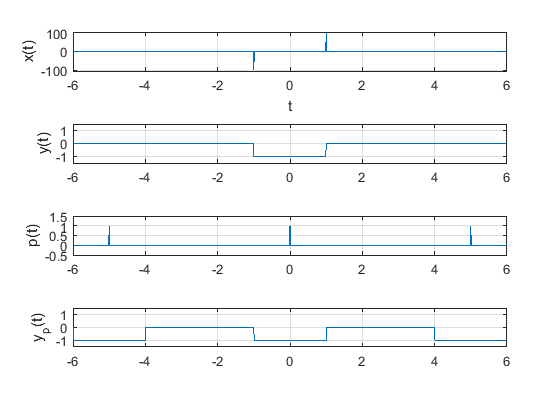


tstep = 1e-2;
t = -6:tstep:6;
t_long = -12:tstep:12;

x_t = (1/tstep)*( (-1)*double(t==-1) +  (+1)*double(t==1))  ;
y_t = tstep*cumsum(x_t);

subplot(411),plot(t,x_t),grid on,xlabel('t'), ylabel('x(t)'),ylim([-105 105]), xlim([-6 6])
subplot(412),plot(t,y_t),grid on, ylabel('y(t)'),ylim([-1.5 1.5]), xlim([-6 6])

p_t = double( (t==-5) | (t==0) | (t==5) );
yp_t = conv(y_t,p_t);

subplot(413), plot (t,p_t),grid on, ylim([-0.5 1.5]), xlim([-6 6]), ylabel('p(t)')
% take only "middle-part" of yp(t)
L = length(yp_t);  % change later to fetch indexes from t definition
subplot(414), plot (t,yp_t(floor(L/4):floor(3*L/4))),grid on, ylim([-1.5 1.5]), ylabel('y_p(t)')

## Prep-Exercise-2

clear all, close all;
display('Prep Exercise 2')

Prep Exercise 2


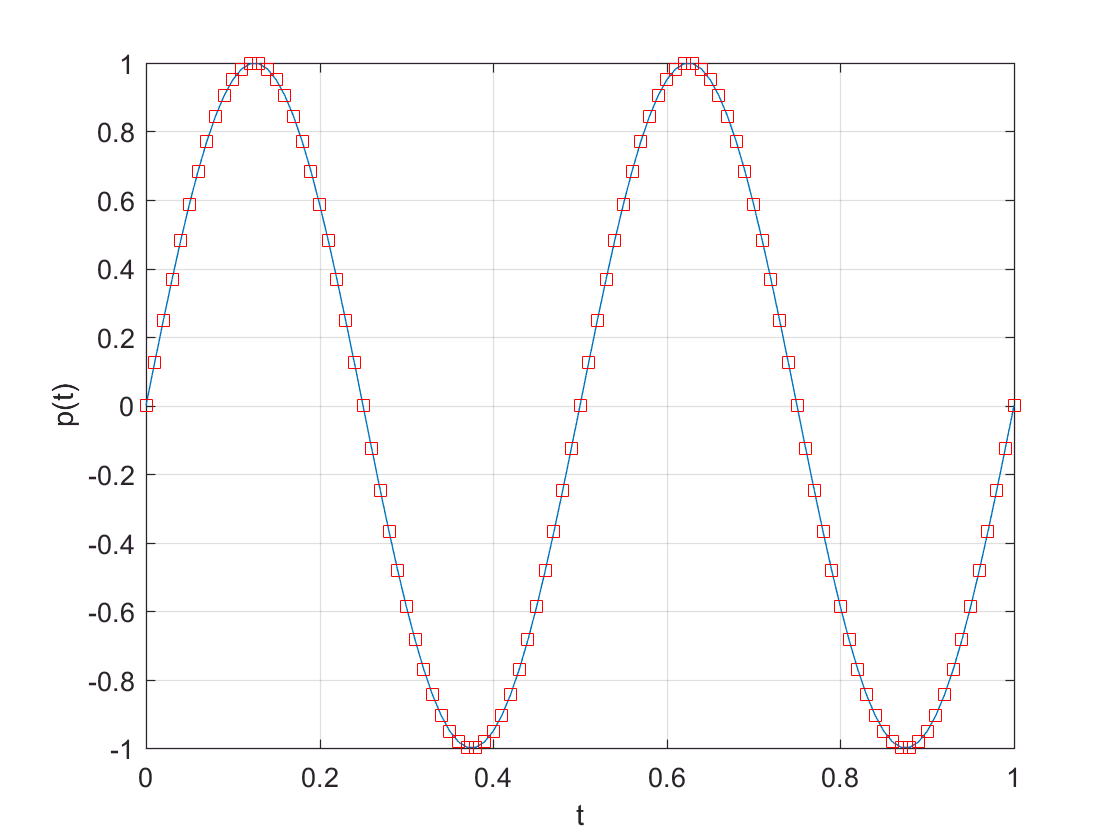


t = 0:1e-2:1;
phi_t = 4*pi*t-pi/2;
p_t     = cos(phi_t);
p_t_bis = 0.5*( exp(j*(phi_t)) + exp(-j*(phi_t)) );

figure(1)
plot(t,p_t), grid on, hold on
plot(t,p_t_bis,'rs'),hold off, xlabel('t'),ylabel('p(t)')

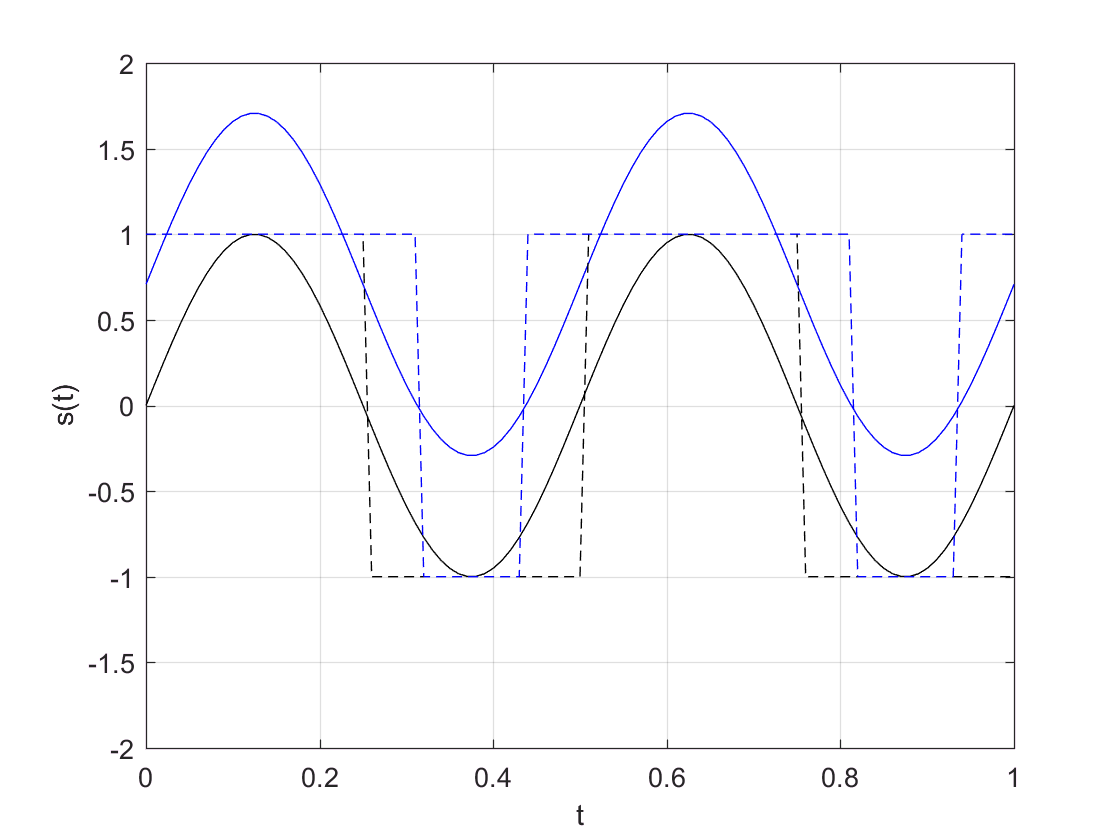


% extension with signum and controlling duty cycle for resulting square function
s_t_d50 = sign(p_t);
s_t_d25 = sign(p_t - cos(pi/4) );

figure(2)
plot(t,p_t,'k',t,(p_t - cos(pi/4)),'b'), grid on, hold on
plot(t,s_t_d50,'k--',t,s_t_d25,'b--'),hold off, xlabel('t'),ylabel('s(t)'), ylim([-2 2])

## Prep-Exercise-3

clear all, close all;
display('Prep Exercise 3')

Prep Exercise 3


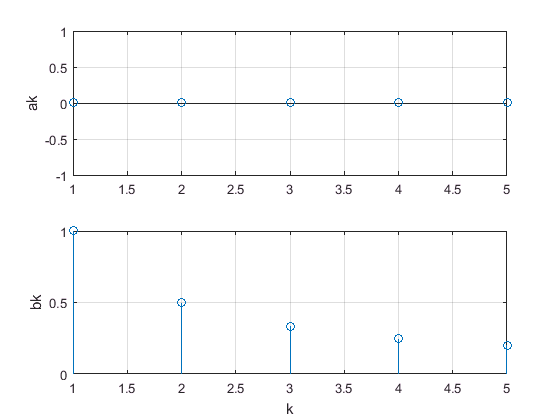


% PARAMETERS
f0 =   1   ;  % fundamental frequency (Hz)
k  = 1:1:5 ;     % harmonic index
ak = zeros(1,5);
bk = 1./k;

figure()
subplot(211),stem(k,ak), grid on, ylabel('ak')
subplot(212),stem(k,bk), grid on, ylabel('bk'), xlabel('k')